xlsxname = '220509_応力_sus無'; %ファイルの名前

data = readmatrix(append('C:\Users\tkode\デスクトップ\マルチチャンネルファイバー\220509\excel_抜出\',xlsxname,'.xlsx'));
x = data(2:end,2:end);
l = ones(size(x)).*data(1,2:end);
t = ones(size(x)).*data(2:end,1);

mesh(t,l,x)
xlabel("経過時間")
ylabel("ファイバー長さ")
zlabel("周波数変化")
zlim([-80 20]) %比較するならそろえよう

h =   Figure (1) のプロパティ:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  すべてのプロパティ を表示


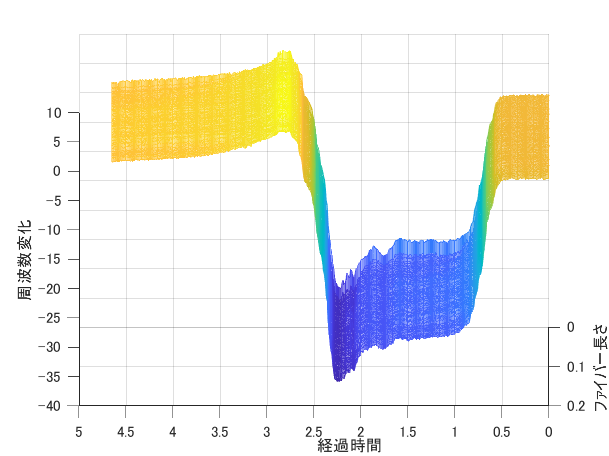

f = zeros(4,4,360);
for n = 1:360
    f(:,:,n) = view(n,30);
end